# Getting Started with Advanced Logger for MATLAB

## Overview

Advanced Logger for MATLAB provides configurable logging capabilites for MATLAB applications. 

 This logger can be configured to write to multiple outputs:

- A log file in text format

- Command window output

- A public event that can be listened to (for example, if you want to show the user a log of informational events in your MATLAB app)

Each of these outputs can be individually configured with the minimum severity level of messages to be written. 

Give your logger a unique name and it will be globally available as a singleton instance. This is because a single instance of Logger must manage the log file being written to.  You can access the logger from multiple places in your code given its unique name.  (There is no need to pass around the logger's object handle throughout your code!)

## Examples:

### Creating a Logger Instance

Create your logger and give it a unique name like this:

logObj = mlog.Logger("MyApp");
disp(logObj)

  Logger with properties:

                             Name: "MyApp"
                          LogFile: "C:\Users\rjackey\AppData\Local\Temp\MyApp_log.txt"

   Log Level Thresholds:
                    FileThreshold: INFO
           CommandWindowThreshold: WARNING
    MessageReceivedEventThreshold: MESSAGE

   Messages:
                       BufferSize: 1000
                         Messages: [0×1 mlog.Message]
                      LastMessage: [0×1 mlog.Message]
                     MessageTable: [0×3 table]



### Writing Messages

You can get the logger instance and write a message like this:

logObj = mlog.Logger("MyApp");
logObj.warning("My warning message");

	MyApp Logger: WARNING My warning message


You have the choice of using functional or object notation.  The commands may be written like this, with logObj as an input:

warning(logObj,"My warning message");

	MyApp Logger: WARNING My warning message


Or like this, with logObj., then the method (function) name:

logObj.warning("My warning message");

	MyApp Logger: WARNING My warning message


#### Write a message from inside a function or method

From within a function or class method, you can use the same syntax, retrieving a reference to the same logger by its unique name.

logObj = mlog.Logger("MyApp");
logObj.error("My error message");

	MyApp Logger: ERROR   My error message


### Write a message providing sprintf arguments

You can pass sprintf arguments directly into the write function:

logObj.error("Unable to locate file: %s", "myfile.txt");

	MyApp Logger: ERROR   Unable to locate file: myfile.txt


### Providing the message level as a separate input

You may also utilize the write method to provide the log level as an input:

level = mlog.Level.WARNING;
logObj.write(level, "My warning message");

	MyApp Logger: WARNING My warning message


### Passing MException errors directly to the logger

You can also directly pass a MException, for example from a try/catch. If you use the write method without specifying a level, it will default to use ERROR.

logObj = mlog.Logger("MyApp");
try
    error("errorType:errorID","Operation failed");
catch err
    logObj.write(err);
end

	MyApp Logger: ERROR   Operation failed
		> LiveEditorEvaluationHelperE517627992 (line 14)


### Reviewing the log file

You can find the log file location this way. The log file location can be customized.

logObj = mlog.Logger("MyApp");
logFile = logObj.LogFile;
open(logFile);

### Configure logging severity settings

First, get the logger:

logObj = mlog.Logger("MyApp");

Now you can customize the severity settings indicating what to log. You can informally specify these using text:

logObj.FileThreshold = "INFO";
logObj.CommandWindowThreshold = "WARNING";
logObj.MessageReceivedEventThreshold = "MESSAGE";

You can optionally specify these more formally in enumeration format. Using this format enables tab completion to assist in typing the syntax correctly:

logObj.FileThreshold = mlog.Level.INFO;
logObj.CommandWindowThreshold = mlog.Level.WARNING;
logObj.MessageReceivedEventThreshold = mlog.Level.MESSAGE;

#### Severity Levels:

The available severity levels in descending order are:

- **FATAL**: Only fatal error level messages are logged

- **CRITICAL**: Only critical error level messages or above are logged

- **ERROR**: Only error level messages or above are logged

- **WARNING**: Only warning level messages or above are logged

- **INFO**: Informational messages or above are logged

- **MESSAGE**: Messages or above are logged

- **DEBUG**: Debugging messages or above are logged

Additionally, if you want to disable an option completely, use the level:

         0. **NONE** - no messages are logged

Do not rely on the numeric values of these levels, as more may be added or inserted in the future. 

### Sending a message to a dialog window

If you are using Logger in a MATLAB App, you may also want to send certain errors and warnings to a dialog window. You can do this by storing the message and calling the `toDialog()` function.

Assume you have a MATLAB app created in App Designer, and it's figure window is stored as:

app.UIFigure = uifigure;

Generate a log message and send it to a dialog. You need to provide the figure that the dialog will be added to.

logObj = mlog.Logger("MyApp")

logObj =   Logger with properties:

                             Name: "MyApp"
                          LogFile: "C:\Users\rjackey\AppData\Local\Temp\MyApp_log.txt"

   Log Level Thresholds:
                    FileThreshold: INFO
           CommandWindowThreshold: WARNING
    MessageReceivedEventThreshold: MESSAGE

   Messages:
                       BufferSize: 1000
                         Messages: [7×1 mlog.Message]
                      LastMessage: [1×1 mlog.Message]
                     MessageTable: [7×3 table]

  Recent Messages:

                Time             Level                                      Text                                  
         ___________________    _______    _______________________________________________________________________

    1    2022-02-22 11:55:27    WA

msgObj = logObj.write("ERROR","Send this error to a dialog")

	MyApp Logger: ERROR   Send this error to a dialog


msgObj =   Message with properties:

         Time: 2022-02-22 11:55:27
        Level: ERROR
         Text: "Send this error to a dialog"
       Source: [1×1 mlog.Logger]
    EventName: 'MessageReceived'


msgObj.toDialog(app.UIFigure, "Optional Dialog Title");

### Configuring a callback for messages received

Let's assume you have a MATLAB App with a listbox to display a log of status messages. In your app, do the following:

- Add a table called `MessageDisplay` to your app

- Add a property called `MessageListener` to your app and add a `startupFcn` callback

- Add a `startupFcn` callback to your app

- In `startupFcn`, create a listener to the Logger's `MessageReceived` event. Configure this listener to run a callback you will write each time the event occurs. Assume this callback function is named `onMessageReceived`:

This first section of code can be configured right from App Designer instead of handwritten, but it's written out here for demonstration. The final product will look like the snapshot right below it. Your app will need to have the code and the callback shown later in this section.

app.UIFigure = uifigure('Position',[100 100 400 150]);
app.Grid = uigridlayout(app.UIFigure,[1 1]);
app.MessageDisplay = uitable(app.Grid);

This goes in your `startupFcn`:

logObj = mlog.Logger("My Logging App");
app.MessageListener = event.listener(logObj, ...
    "MessageReceived", @(src,evt)onMessageReceived(app,src,evt) );

Let's send a few test messages:

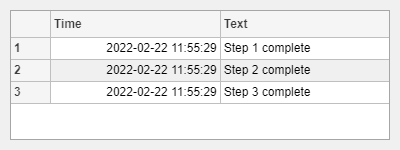

logObj.write("MESSAGE","Step 1 complete");
logObj.write("MESSAGE","Step 2 complete");
logObj.write("MESSAGE","Step 3 complete"); drawnow %using drawnow to force figure to render snapshot here

### Callback Function

This is the callback function you need to implement for the app to update the table when messages are received: 

function onMessageReceived(app,src,evt) %#ok<INUSD>
% This callback will update the MessageDisplay each time a new message is
% received

% Since we are listening to your logObj, it is already provided to you
% as the source of the callback event:
logObj = src;

% Remove the level from the table. Just display time and message
tableData = logObj.MessageTable;
tableData = removevars(tableData, "Level");

% Display the messages in the table
app.MessageDisplay.Data = tableData;

end %function

Copyright 2018-2022 The MathWorks Inc.